# Introduction

This notebook is intended to provide an basic example of how to load and perform some basic preprocessing to hyperspectral data in ENVI format using Python.

This notebook was designed as a basic demonstration on how to load the data corresponding to the Histological Hyperspectral Glioblastoma Dataset (HistologyHSI-GB) [REF].

`## Maybe more information here ... and copyright`

The following code pretends to load a HS cube and make some simple processing. 

## 1) Setting up the environment and downloading the example data

#### Toolbox:

Image Processing Toolbox Hyperspectral Imaging Library  is needed to use the *hypercube* function. The function is used to read multidimensional image data from files and its related wavelengths. 

clear; clc; close all;
if sum("Image Processing Toolbox Hyperspectral Imaging Library" == matlab.addons.installedAddons().Name)
    disp('All Toolbox required installed');
else 
    disp('Image Processing Toolbox Hyperspectral Imaging Library Missing, install it before continuing.');
end

All Toolbox required installed


#### Data:

The data used on this notebook correspond to a folder containing hyperspectral data from a brain histological slide from the HistologyHSI-GB dataset. The hyperspectral cubes from the histological slide and the white and dark references are stored as ENVI files, the standard format for storing hyperspectral images. The ENVI format consists of a flat-binary raster file with an accompanying ASCII header file.

The folder contains the ENVI files from the histological slide and the necessary files for the calibration (dark and white reference). Additionally, the folder contains a synthetic RGB image extracted from the hyperspectral cube.

disp('Download the data from the repository.')

Download the data from the repository.


url = 'https://nimbus.iuma.ulpgc.es/s/egkXbJTcAaxyqCs/download/ROI_01_C01_T.zip'; 
filename = 'ROI_01_C01_T.zip';
outputFolder = 'path_to_output_folder\';


f = waitbar(0,'Please wait...');
websave(filename, url);
waitbar(.33,f,'Downloading the data');

unzip(filename, outputFolder);
waitbar(1,f,'Finishing');

pause(1)
close(f)
disp('Data downloaded to your folder.')

Data download to your folder.


## 3) Load the hyperspectral images and check their sizes

The raw hyperspectral image has a dimension of (800, 1004, 826), where the first two dimensions correspond to the spatial information (800x1004 pixels), and the third dimension corresponding to the spectral information (826 bands).

The white and dark reference have a dimension of (1, 1004, 826), since there is only information about a single line across the field of view of the camera. These reference were obtained as an average of 100 consecutive measurements of the white and dark references.

% Define the file names for the raw image, the white reference and the dark
raw_file_name = [outputFolder,filename(1:end-4),'\raw.hdr'];
white_reference_file_name = [outputFolder,filename(1:end-4),'\whiteReference.hdr'];
dark_reference_file_name = [outputFolder,filename(1:end-4),'\darkReference.hdr'];

% # Use the function read_hyperspectral_cube to load the ENVI files into numpy arrays. The spectral bands (wavelengths) for the white and dark references are the same ones ...
% we have for the hyperspectral cube, so it is no necesary to also get them.
fprintf('Load raw data, white reference, and \ndark reference into the workspace.')

Load raw data, white reference, and 
 dark reference into the workspace.

[raw_hyperspectral_image, wavelengths] = read_hyperspectral_cube(raw_file_name);
[white_reference,~]= read_hyperspectral_cube(white_reference_file_name);
[dark_reference, ~] = read_hyperspectral_cube(dark_reference_file_name);

% We need the data to be double type in order to work with it
disp('Converting data from unit16 to double')

Converting data from unit16 to double


raw_hyperspectral_image = double(raw_hyperspectral_image) / double(intmax('uint16'));
white_reference = double(white_reference) / double(intmax('uint16'));
dark_reference = double(dark_reference) / double(intmax('uint16'));

% Display data dimensions:
disp('Image dimensions:')

Image dimensions:


fprintf('Raw hyperspectral image dimensions: (%d, %d, %d)\n', + size(raw_hyperspectral_image));

Raw hyperspectral image dimensions: (800, 1004, 826)


fprintf('White reference dimensions: (%d, %d, %d)\n', + size(white_reference));

White reference dimensions: (1, 1004, 826)


fprintf('Dark reference dimensions: (%d, %d, %d)\n', + size(dark_reference));

Dark reference dimensions: (1, 1004, 826)



% Display some information about the spectral bands:
disp('Spectral information:')

Spectral information:


fprintf('Min. wavelength (nm): %.2f\n', wavelengths(1));

Min. wavelength (nm): 400.48


fprintf('Max. wavelength (nm): %.2f\n', wavelengths(end));

Max. wavelength (nm): 1000.73


fprintf('Number of spectral bands: %d\n', size(wavelengths,1));

Number of spectral bands: 826


fprintf('Distance between consecutive spectral bands (nm): %.2f\n', mean(diff(wavelengths)));

Distance between consecutive spectral bands (nm): 0.73


## 4) Perform the calibration and the preprocessing

% Perform the hyperspectral image calibration
disp('Performing HS image calibration.')

Performing HS image calibration.


calibrated_hyperspectral_image = hyperspectral_calibration(raw_hyperspectral_image, white_reference, dark_reference);
disp('HS image calibrated.')

HS image calibrated.



disp('Performing band reduction')

Performing band reduction


% TODO: Optional. Perform the band reduction.
[band_reduced_hyperspectral_image, reduced_wavelengths] = band_reduction(calibrated_hyperspectral_image, wavelengths,3);


% Display data dimensions:
disp('Image dimensions after preprocessing:')

Image dimensions after preprocessing:


fprintf('Calibrated hyperspectral image dimensions:(%d, %d, %d)\n', size(calibrated_hyperspectral_image));

Calibrated hyperspectral image dimensions:(800, 1004, 826)


fprintf('Band-reduced hyperspectral image dimensions: (%d, %d, %d)\n', size(band_reduced_hyperspectral_image));

Band-reduced hyperspectral image dimensions: (800, 1004, 275)



% Display some information about the reduced spectral bands:
disp('Spectral information after preprocessing:')

Spectral information after preprocessing:


fprintf('Min. wavelength (nm): %.2f\n', reduced_wavelengths(1));

Min. wavelength (nm): 400.48


fprintf('Max. wavelength (nm): %.2f\n', reduced_wavelengths(end));

Max. wavelength (nm): 998.55


fprintf('Number of spectral bands: %d\n', size(reduced_wavelengths,1));

Number of spectral bands: 275


fprintf('Distance between consecutive spectral bands (nm): %.2f\n', mean(diff(reduced_wavelengths)));

Distance between consecutive spectral bands (nm): 2.18


## 5) Representation of the information from the hyprespectral data

#### Visualizing the spatial information for different spectral bands

fprintf('Visualizing the spatial information for \ndifferent spectral bands.');

Visualizing the spatial information for 
different spectral bands.

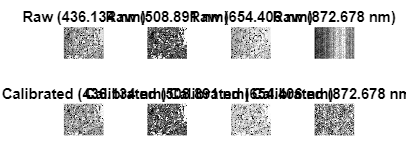

f = figure;
set(f, 'Position', [0, 0, 1000, 400]);

band_list = [50 150 350 650];

for idx = 1:numel(band_list)
    current_band = band_list(idx);
    
    subplot(2, numel(band_list), idx);
    imshow(imadjust(raw_hyperspectral_image(:,:,current_band)));
    title(['Raw (' num2str(wavelengths(current_band)) ' nm)'], 'FontSize', 8);
    axis off;
    
    subplot(2, numel(band_list), numel(band_list) + idx);
    imshow(imadjust(calibrated_hyperspectral_image(:,:,current_band)));
    title(['Calibrated (' num2str(wavelengths(current_band)) ' nm)'], 'FontSize', 8);
    axis off;
end

#### Visualizing the spectral information of different pixels

fprintf('Visualizing the spectral information \nof different pixels.')

Visualizing the spectral information \n of different pixels.


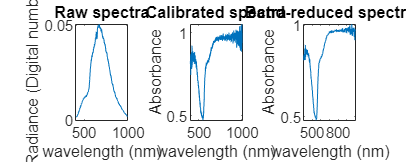

f = figure;
set(f, 'Position', [0, 0, 1000, 400]);

axarr = zeros(1, 3);
for idx = 1:3
    axarr(idx) = subplot(1, 3, idx);
end

x_coordinate = 500;
y_coordinate = 600;

% Represent some bands from the raw image
plot(axarr(1), wavelengths, squeeze(raw_hyperspectral_image(y_coordinate, x_coordinate, :)));
title(axarr(1), 'Raw spectra');
xlabel(axarr(1), 'wavelength (nm)');
ylabel(axarr(1), 'Radiance (Digital number)');
xlim(axarr(1), [wavelengths(1), wavelengths(end)]);

plot(axarr(2), wavelengths, squeeze(calibrated_hyperspectral_image(y_coordinate, x_coordinate, :)));
title(axarr(2), 'Calibrated spectra');
xlabel(axarr(2), 'wavelength (nm)');
ylabel(axarr(2), 'Absorbance');
xlim(axarr(2), [wavelengths(1), wavelengths(end)]);

plot(axarr(3), reduced_wavelengths, squeeze(band_reduced_hyperspectral_image(y_coordinate, x_coordinate, :)));
title(axarr(3), 'Band-reduced spectra');
xlabel(axarr(3), 'wavelength (nm)');
ylabel(axarr(3), 'Absorbance');
xlim(axarr(3), [reduced_wavelengths(1), reduced_wavelengths(end)]);

## Define helper functions to load and preprocessing the hyperspectral data

function [hyperspectral_data, wavelengths] = read_hyperspectral_cube(file_name)
    % Function used to read an ENVI hyperspectral image, and return a
    % data structure containing the 3D hyperspectral cube
    % 
    % Parameters
    % ----------
    % file_name : str
    %     The file location of the ENVI header related to the hyperspectral data.
    % 
    % Returns
    % -------
    % hyperspectral_data: ndarray
    %     3-dimensional array containing the hyperspectral cube
    % wavelengths: ndarray
    %     1-dimensional array containing the spectral bands corresponding to
    %     the hyperspectral cube
    
    ENVI_structure  = hypercube(file_name);
    hyperspectral_data = ENVI_structure.DataCube;
    wavelengths = ENVI_structure.Wavelength;

end

function calibrated_hyperspectral_image  = hyperspectral_calibration(raw_data, white_reference, dark_reference)
    % Perform the calibration of a hyperspectral imaging using a white and
    % dark reference images.
    % 
    % Parameters
    % ----------
    % raw_data : Array containing the raw hyperspectral cube
    % white_reference : Array containing the white reference
    % dark_reference : Array containing the dark reference
    %
    % Returns
    % -------
    % Calibrated hyperspectral cube
    
    
    calibrated_hyperspectral_image = (raw_data-dark_reference)./(white_reference-dark_reference);
      
end

function [band_reduced_cube, wavelength_reduced] = band_reduction(input_data, wavelenghts, n)
    % Perform the band reduction to the hyperspectral cube
    % 
    % Parameters
    % ----------
    % input_data : 3D ndarray
    %     Array containing the raw hyperspectral cube
    % wavelengths : numpy array containing the spectral bands corresponding to
    % the hyperspectral cube
    % Returns
    % -------
    % band_reduced_cube: ndarray
    %     3-dimensional numpy array containing the hyperspectral cube
    % wavelength_reduced: ndarray
    %     1-dimensional numpy array containing the spectral bands corresponding to
    %     the hyperspectral cube
    
   
    % Iterate over the bands in the reduced array
    counter = 1;
    for i = 1 : n: floor(size(input_data,3)/n)*n
        % Calculate the average along the third dimension (bands)
        band_reduced_cube(:, :, counter) = mean(input_data(:,:,i:i+n-1), 3);
        counter = counter + 1;
    end
    wavelength_reduced = wavelenghts(1 : n : floor(size(input_data,3)/n)*n);

end